close all
clear
clc

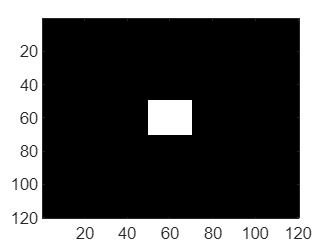

A = zeros(120, 120, 3);
A(size(A)/2-10:size(A)/2+10, size(A)/2-10:size(A)/2+10, :) = 10;
imagesc(A);

x = 50; 
y = 50; 
z = 1;



alfa = 0.02;
eta = 0.01;
delta = 0.2;
beta = 3.5;


Ant = ant;
init_voxel = [x, y, z];
Ant.energy = 1 + alfa;
Ant.x = x; 
Ant.y = y; 
Ant.z = z;
B = Pheromone_map;
B.A = A;
pheromone_map = B.initialize_matrix(A);
pheromone = [];
e_death = 1;
tic
for i=1:100
    pheromone_map(Ant.x, Ant.y, Ant.z, 2) = Ant.mark_voxel(pheromone_map, Ant.x, Ant.y, Ant.z);
    pheromone_map(Ant.x, Ant.y, Ant.z, 1) = Ant.pheromone_release(A, eta, Ant.x, Ant.y, Ant.z);
    pheromone = [pheromone, Ant.pheromone_release(A, eta, Ant.x, Ant.y, Ant.z) - eta]
    Ant.energy = Ant.update_energy(Ant.energy, alfa, pheromone(i), sum(pheromone)/numel(pheromone))
    if Ant.energy < e_death
        disp('Morte della formica')
        break
    end
    output = Ant.evaluate_destination(pheromone_map, delta, beta, Ant.x, Ant.y, Ant.z);
    if isempty(output) == 1
        disp('vuoto')
        break
    end
    pheromone_map(Ant.x, Ant.y, Ant.z, 2) = Ant.leave_voxel(pheromone_map, Ant.x, Ant.y, Ant.z);
    Ant.x = output(1);
    Ant.y = output(2);
    Ant.z = output(3);
end

pheromone = 10

Ant =   ant with properties:

         x: 50
         y: 50
         z: 1
    number: 1
    energy: 1.0200


output =     49    50     2


pheromone =     10     0


Ant =   ant with properties:

         x: 49
         y: 50
         z: 2
    number: 1
    energy: 1


output =     50    50     1


pheromone =     10     0    10


Ant =   ant with properties:

         x: 50
         y: 50
         z: 1
    number: 1
    energy: 1.0100


output =     49    51     1


pheromone =     10     0    10     0


Ant =   ant with properties:

         x: 49
         y: 51
         z: 1
    number: 1
    energy: 0.9900


Morte della formica


toc

Elapsed time is 0.170206 seconds.


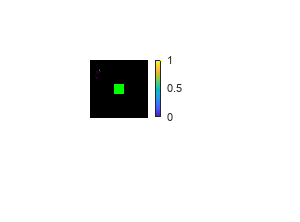

PM = pheromone_map(:, :, :, 1);
imshowpair(A,PM), colorbar;

orthosliceViewer(PM);